% Specify the input audio file
inputFile ='noise_removed.wav';
[x, fs] = audioread(inputFile);

% Loop through the frames and process them as needed
numFrames = size(frames, 2)

Execution of script frames as a function is not supported:
C:\Users\Lenovo\Documents\MATLAB\DSP\Digital-Signal-Processing\project\frames.mlx

for i = 1:numFrames
    currentFrame =sprintf('frame%d.wav', i)
    [x,fs]=audioread(currentFrame)
    N=length(x);
    n=(0:N-1);
    W=0.54-0.46*cos(2*pi*n/(N-1));
    windowed=x.*W;
    y=fft(windowed,512);
    y=y(1:257)
    [coeffs,delta,deltaDelta,loc] = mfcc(y,fs);
    mfcc(y,fs)
end

for i=1:numFrames
    currentFrame =sprintf('frame%d.wav', i);
    [x,fs]=audioread(currentFrame);
    plot(x)
end

Unrecognized function or variable 'numFrames'.

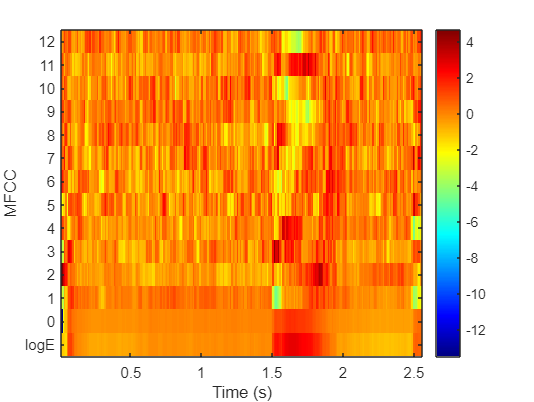

[audioIn,fs] = audioread("C:\Users\Lenovo\Documents\MATLAB\DSP\Digital-Signal-Processing\audio_files\two.wav");
[coeffs,delta,deltaDelta,loc] = mfcc(audioIn,fs);
mfcc(audioIn,fs)

x=calculate_dtw(coeffs,coeffs)

Error using statslib.internal.pdist2
N-D arrays are not supported.

Error in pdist2 (line 158)
[varargout{1:nargout}] = statslib.internal.pdist2(X,Y,varargin{:});

Error in frames>calculate_dtw (line 30)
    distance_matrix = pdist2(mfcc_seq1, mfcc_s

function dtw_distance = calculate_dtw(mfcc_seq1, mfcc_seq2)
    % Step 1: Compute the pairwise distance matrix
    distance_matrix = pdist2(mfcc_seq1, mfcc_seq2, 'euclidean');

    % Step 2: Initialize accumulated cost matrix
    accumulated_cost = zeros(size(distance_matrix));

    % Step 3: Dynamic Programming
    for i = 1:size(mfcc_seq1, 1)
        for j = 1:size(mfcc_seq2, 1)
            accumulated_cost(i, j) = distance_matrix(i, j) + min([
                accumulated_cost(max(i-1, 1), j),     % insertion
                accumulated_cost(i, max(j-1, 1)),     % deletion
                accumulated_cost(max(i-1, 1), max(j-1, 1))  % match
            ]);
        end
    end

    % Step 4: Backtracking
    i = size(mfcc_seq1, 1);
    j = size(mfcc_seq2, 1);

    while i > 1 || j > 1
        dtw_path(i, j) = 1;  % Mark the path in a binary matrix
        if i > 1 && j > 1
            [~, idx] = min([accumulated_cost(i-1, j), accumulated_cost(i, j-1), accumulated_cost(i-1, j-1)]);
            switch idx
                case 1
                    i = i - 1;  % move up (insertion)
                case 2
                    j = j - 1;  % move left (deletion)
                case 3
                    i = i - 1;  % move diagonally (match)
                    j = j - 1;
            end
        elseif i > 1
            i = i - 1;
        else
            j = j - 1;
        end
    end
    dtw_path(1, 1) = 1;

    % Step 5: Calculate DTW Distance
    dtw_distance = sum(distance_matrix(logical(dtw_path)));

end

